2. Построить график поверхности $z=1-x^2 -y^2$ при 0 < x < 1, 0 < y < 1 с использованием функций shading interp, diffuse, colormap() и вычислить объем, заключенный между укзанной поверхностью и плоскостью z = 0$\left(V\approx \sum \sum z\left(x_i \;,y_k \right)\Delta x_i \;\Delta y_k \right)$.

clear
clc
close all

x1 = linspace(0, 1)

x1 =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


x2 = linspace(0, 1)

x2 =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949



[X1, X2] = meshgrid(x1, x2)

X1 =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949
         0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    

X2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    


Z = 1 - X1.^2 - X2.^2

Z =     1.0000    0.9999    0.9996    0.9991    0.9984    0.9974    0.9963    0.9950    0.9935    0.9917    0.9898    0.9877    0.9853    0.9828    0.9800    0.9770    0.9739    0.9705    0.9669    0.9632    0.9592    0.9550    0.9506    0.9460    0.9412    0.9362    0.9310    0.9256    0.9200    0.9142    0.9082    0.9019    0.8955    0.8889    0.8821    0.8750    0.8678    0.8603    0.8527    0.8448    0.8368    0.8285    0.8200    0.8113    0.8025    0.7934    0.7841    0.7746    0.7649    0.7550
    0.9999    0.9998    0.9995    0.9990    0.9983    0.9973    0.9962    0.9949    0.9934    0.9916    0.9897    0.9876    0.9852    0.9827    0.9799    0.9769    0.9738    0.9704    0.9668    0.9631    0.9591    0.9549    0.9505    0.9459    0.9411    0.9361    0.9309    0.9255    0.9199    0.9141    0.9081    0.9018    0.8954    0.8888    0.8820    0.8749    0.8677    0.8602    0.8526    0.8447    0.8366    0.8284    0.8199    0.8112    0.8024    0.7933    0.7840    0.7745    0.7648    0

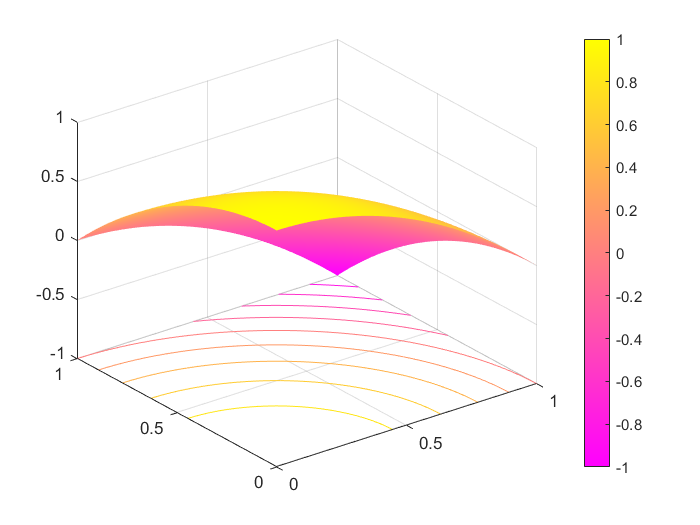


figure
surfc(X1, X2, Z)
grid on
shading interp
colorbar
colormap spring

diffuse(X1, X2, Z, [2, 2, 2])

ans =     0.5774    0.5832    0.5889    0.5946    0.6002    0.6058    0.6113    0.6168    0.6223    0.6276    0.6330    0.6383    0.6435    0.6487    0.6539    0.6590    0.6641    0.6691    0.6741    0.6790    0.6839    0.6888    0.6936    0.6984    0.7031    0.7078    0.7124    0.7170    0.7215    0.7260    0.7304    0.7348    0.7391    0.7433    0.7475    0.7516    0.7556    0.7596    0.7635    0.7673    0.7710    0.7746    0.7781    0.7815    0.7848    0.7880    0.7910    0.7939    0.7967    0.7994
    0.5832    0.5890    0.5947    0.6004    0.6060    0.6116    0.6172    0.6226    0.6281    0.6335    0.6388    0.6441    0.6494    0.6546    0.6598    0.6649    0.6700    0.6750    0.6800    0.6850    0.6899    0.6947    0.6996    0.7043    0.7091    0.7138    0.7184    0.7230    0.7275    0.7320    0.7365    0.7408    0.7452    0.7494    0.7536    0.7577    0.7618    0.7658    0.7697    0.7735    0.7772    0.7808    0.7844    0.7878    0.7911    0.7943    0.7974    0.8003    0.8031   




V = 0.01*0.01*sum(sum(Z(:)))

V = 0.3300